# Laboratório de Controle - Aula 5 - 2022/1

## Projeto de controladores e análise de desempenho

## **Nome**: 

Assista o [video](https://classroom.google.com/c/NTE0NDk4OTQ4Mjgw/m/MzYzNDQyMTc4MTU4/details) sobre esta aula.

turma=0;
I=0;
[h10,h20,q,a1,a2]=init(turma,I)
Ar=pi*12.5^2;
datetime('now')
pwd
tic

**Sistema de dois tanques acoplados utilizado nesta aula**

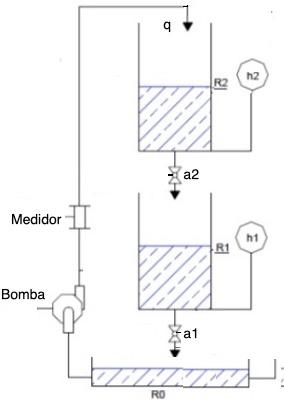

A bomba produz uma vazão $q$ no reservatório superior R2, que desce para R1 através da válvula manual $a_2$. A água de R1 escoa para R0 através da válvula manual $a_1$.

Equações que regem seu comportamento:


$$\frac{dh_1}{dt}=-\frac{a_1}{A}\sqrt{2gh_1}+\frac{a_2}{A}\sqrt{2gh_2}$$



$$\frac{dh_2}{dt}=-\frac{a_2}{A}\sqrt{2gh_2}+\frac{100}{6A}q$$


Vazão q em $l/min$

Nível em $cm$

Gravidade $g=981\frac{cm}{s^2}$

Área dos tanques $A=\pi 12.5^2   cm^2$

Vazão através da válvula $a_1$: $(6/100)a_1\sqrt{2gh_1}$, em $l/min$

Ponto de operação do sistema:

Os dois níveis se estabilizam quando a vazão que passa por $a_1$ é igual a que passa por $a_2$, sendo iguais a $q$. Os niveis $h_1$ e $h_2$ dependem dos valores de $a_1$ e $a_2$, respectivamente. Para obter o ponto de operação, basta fazer as derivadas iguais a zero.

O ponto de operação é definido pela vazão $q$ e pelos níveis $h_1$ e $h_2$, que por sua vez depende das aberturas $a_1$ e $a_2$, respectivamente.

Linearização:

Definindo:


$$u=q-q_0$$



$$x=h-h_0$$


$\dot{x}=\dot{h}$ (para o sistema não linear tem-se $h$ para representar o nível e para o sistema linear tem-se $x$).

e usando a expansão em séries de Taylor na parte não linear da equação de nível:


$$\frac{df(x,q)}{dx}=\frac{a_1\sqrt{2g}}{2\sqrt{x_0}}=a_1\sqrt{g/2x_0} $$


resultam as equações de $x_1(t)$ e $x_2(t)$ linearizadas em torno de $x_{10},x_{20},q_0$:


$$A\frac{dx_2}{dt}=\frac{100}{6}q-a_2\sqrt{\frac{g}{2x_{20}}}x_2$$



$$A\frac{dx_1}{dt}=-a_1\sqrt{\frac{g}{2x_{10}}}x_1+a_2\sqrt{\frac{g}{2x_{20}}}x_2$$


Destas equações pode-se obter o modelo em variáveis de estado


$$\dot{x}=Ax+Bu \\
y = Cx
$$


e o modelo por função de transferência 


$$\frac{Y(s)}{U(s)}=G(s)=C(sI-A)^1B$$


Vazão através de $a_1$ no modelo linearizado:$(6/100)a_1\sqrt{981/(2h10)}$, em $l/min$

**Atividade 1: Simulação do sistema não linear em malha aberta**

*Simular o modelo não linear no Matlab para o ponto de operacão definido em malha aberta, escolhendo o tempo T1 adequado.*

*A função abaixo, *nivel_2tanques_mf.m, é similar a função nivel_2tanques.m usada na aula 3. A diferença é a substituição da entrada de vazão q pelo sinal de controle em malha fechada u, vindo de um controlador PI.

*function dh = nivel_2tanques(t,h,a1,a2,q,Ref,Kp,Ki)*

*g=981;*

*A=pi*12.5^2;*

*erro=Ref-h(1);*

*du=erro;*

*u=q + Kp*erro+Ki*h(3); % Controlador PI*

*dh1=-(a1/A)*sqrt(2*g*h(1))+(a2/A)*sqrt(2*g*h(2));*

*dh2=-(a2/A)*sqrt(2*g*h(2))+(100/6)*u/A;*

*dh=[dh1;dh2;du];*

*end*

T1=600; % Escolher
Ref=h10;
Kp=0;
Ki=0;
[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2,q,Ref,Kp,Ki), [0 T1], [0.1;0.1;0]);
qh1=q+Kp*(Ref-h(:,1))+Ki*h(:,3);
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1);legend('h_1','h_2','q');
title('Figura 1: Simulação do sistema não-linear variando a vazão ');
xlabel('Tempo(s)');

1.1 Qual a vazão que passa pela válvula a2 em regime e por que ela se torna constante ?

**Atividade 2: Simulação do sistema em malha fechada: escolha de um ganho proporcional Kp **

O diagrama do sistema de controle com um controlador PID para controle do nível de R1 é mostrado abaixo. Um valor inicial qo de vazão é aplicado que faz os dois níveis ficarem no ponto de operação. O controlador PID compara o nível de referência com h1: sendo iguais, apenas a vazão qo é aplicada.

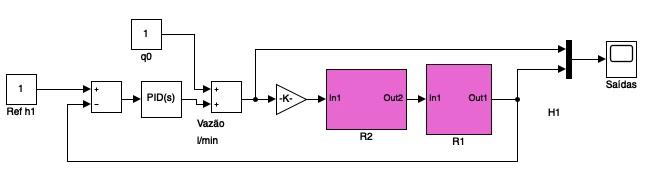

No código a seguir, o sistema linearizado é representado em variáveis de estado por s1. A FT G é necessária para obter ganhos do controlador PID que garantam estabilidade.

A FT G é obtida considerando como saída apenas o nivel h1 de R1 e como entrada a vazão q aplicada, $G(s)=\frac{H_1(s)}{Q(s)}$.

A=[-(a1/Ar)*sqrt(981/(2*h10))   (a2/Ar)*sqrt(981/(2*h20));0 -(a2/Ar)*sqrt(981/(2*h20))];
B=[0;100/(6*Ar)];
C1=[1 0];
D=[];
tt1=toc;
s1=ss(A,B,C1,D);
G=tf(s1); % FT G(s)
[x,t,z]=step(G,T1);
figure;
plot(t,x);
title('Figura 2: Resposta de h_1 ao degrau unitário de vazão');
xlabel('Tempo(s)');ylabel('Nivel h_1');

Lembrando que o LR de G(s) são as raízes de $1+KG(s)=0$, faça o lugar das raízes de G(s) com o comando rlocus  (não coloque no relatório). 

***Dica: se tiver dúvidas, veja a atividade 4 do relatório 4.***

2.1 O que ocorre com as raízes de $1+KG(s)=0$ (polos de malha fechada) quando o ganho K aumenta e qual o efeito sobre a resposta ao degrau?

2.2  Obtenha do LR o valor de K tal que a sobreelevação seja aproximadamente 30%. Faça a simulação abaixo do sistema não linear com este ganho Kp=K, e veja se obtêm UP=30% ou próximo.

Simulação com o ganho Kp.

T2=600; % Rever escolha do tempo de simulação de malha fechada
Ref=h10+5; % Variacao em torno de h10 (5, no caso)
Kp=0;
Ki=0;
[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2,q,Ref,Kp,Ki), [0 T2], [h10;h20;Ref-h10]);
qh1=q+Kp*(Ref-h(:,1))+Ki*h(:,3);
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1,t,r);legend('h_1','h_2','q','Ref');
title('Figura 3: Simulação do sistema para o ganho Kp (UP=30%)');
xlabel('Tempo(s)')
y=h(:,1)-h(1,1);
S=stepinfo(y,t,y(end))

2.3 Faça uma nova escolha de Kp para sobreelevação de 10%, e compare o erro em regime para UP=10% e UP=30%, simulando o código abaixo e justificando.


Ref=h10+5; % Variacao em torno de h10
Kp=0;
Ki=0;
[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2,q,Ref,Kp,Ki), [0 T2], [h10;h20;Ref-h10]);
qh1=q+Kp*(Ref-h(:,1))+Ki*h(:,3);
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1,t,r);legend('h_1','h_2','q','Ref');
title('Figura 4: Simulação do sistema para o ganho Kp (UP=10%)');
xlabel('Tempo(s)')
y=h(:,1)-h(1,1);
S=stepinfo(y,t,y(end))
tt2=toc/tt1

**Atividade 3: Simulação do sistema em malha fechada: escolha de um ganho integral Ki **

Ao fechar a malha de G(s) com o controlador PI, assumindo o valor de Kp dado (Item 2.3), a equação característica de malha fechada é dada por $1+K_I G_{pi}(s)=0$.

Gpi=tf(G.Numerator{1},conv(G.Denominator{1},[1 0])+Kp*conv(G.Numerator{1},[1 0]));


3.1 Faça o LR das raízes de $1+K_I G_{pi}(s)=0$ e comente o que ocorre com os polos de malha fechada e a resposta ao degrau quando o ganho Ki aumenta.

3.2 Escolha um valor de Ki tal que UP seja limitada em 30%. Faça a simulação abaixo e verifique o resultado da escolha. Comente também e explique o erro em regime. 

***Se tiver dúvidas, veja a atividade 2.3 do relatório 4.***

Ref=h10+5;
Ki=0;
[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2,q,Ref,Kp,Ki), [0 T2], [h10;h20;Ref-h10]);
qh1=q+Kp*(Ref-h(:,1))+Ki*h(:,3);
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1,t,r);legend('h_1','h_2','q','Ref');
title('Figura 5: Simulação do sistema para o ganho K_I ');
xlabel('Tempo(s)')
y=h(:,1)-h(1,1);
S=stepinfo(y,t,y(end))
TT=table(h10,q, Ref)

3.3 Qual o aumento de vazão que o controlador produziu na bomba de modo que h1 mudou de h10 para Ref? 

**Atividade 4: Simulação a distúrbio**

4.1 Nessa atividade, interaja com o professor para discutir um distúrbio a ser introduzido na malha de controle (no código abaixo), de modo a verificar se o controlador consegue rejeitá-lo. A simulação começa no ponto de operação com Ref=h10.

Explique o efeito do distúrbio na simulação e se o controlador conseguiu rejeitá-lo e de que forma.

Ref=h10; 
[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2,q,Ref,Kp,Ki), [0 T2], [h10;h20;Ref-h10]);
qh1=q+Kp*(Ref-h(:,1))+Ki*h(:,3);
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1,t,r);legend('h_1','h_2','q','Ref');
title('Figura 6: Simulação do sistema a um distúrbio ');
xlabel('Tempo(s)');
ye=Ref-h(:,1);
IAE=trapz(t,abs(ye))

4.2 Considere a métrica IAE para medir quão bem o controlador PI rejeita o distúrbio. Como escolher Kp e Ki para obter o menor IAE? Subsidie sua resposta com análises de simulações feitas. ***Dica: Se tiver dúvidas, veja a atividade 2.4 do relatório 4.***

[t,h] = ode45(@(t,y) nivel_2tanques_mf(t,y,a1,a2*1.05,q,Ref,Kp*1,Ki*1), [0 T2], [h10;h20;Ref-h10]);
qh1=q+Kp*(Ref-h(:,1)+Ki*h(:,3));
figure;
r=Ref*ones(size(h(:,1)));
plot(t,h(:,1:2),t,qh1,t,r);legend('h_1','h_2','q','Ref');
title('Figura 7: Simulação do sistema a um distúrbio reduzindo o IAE');
xlabel('Tempo(s)');

4.3 Como a ação integral foi calculada na função nivel_2tanques_mf.m que simula o sistema em malha fechada?

4.4 Use o conhecimento adquirido na aula de hoje para sugerir um conjunto de especificações que o controlador de nível deve atender, para, na sua opinião, garantir uma boa resposta.